clc;
clear;
Tuning1 = load("CalibrationDataFixed1.mat");

Tuning1 = Tuning1.data;


% Torques calculated via force plate forces using the jacobian, 

FPy = [];
FPz = [];
MRq = [];
MLq = [];
MRt_read = [];
MLt_read = [];
MRt_cmd = [];
MLt_cmd = [];
ts = 1000;
times = [13.5, 55.4;
    13.7, 60;
    13.7, 63;
    16.2, 66.2;
    13.6, 62];
for i = 1:5
    % Force plate
    FPy = [FPy; Tuning1{i}{2}.Values.Data(times(i, 1)*ts: times(i, 2)*ts)];
    FPz = [FPz; Tuning1{i}{3}.Values.Data(times(i, 1)*ts: times(i, 2)*ts)];
    % Motor angles
    MR_resample = resample(Tuning1{i}{11}.Values.q, Tuning1{i}{1}.Values.Time);
    MRq = [MRq; MR_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    ML_resample = resample(Tuning1{i}{12}.Values.q, Tuning1{i}{1}.Values.Time);
    MLq = [MLq; ML_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];

    % Motor torques (cmd)
    MR_resample = resample(Tuning1{i}{15}.Values.tff, Tuning1{i}{1}.Values.Time);
    MRt_cmd = [MRt_cmd; MR_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    ML_resample = resample(Tuning1{i}{14}.Values.tff, Tuning1{i}{1}.Values.Time);
    MLt_cmd = [MLt_cmd; ML_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    
    % Motor torques (read)
    MR_resample = resample(Tuning1{i}{11}.Values.t, Tuning1{i}{1}.Values.Time);
    MRt_read = [MRt_read; MR_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];
    ML_resample = resample(Tuning1{i}{12}.Values.t, Tuning1{i}{1}.Values.Time);
    MLt_read = [MLt_read; ML_resample.Data(times(i, 1)*ts: times(i, 2)*ts)];

end
clear MR_resample ML_resample


## Transfer force plate data into torques

% From the side of forces:
Fy_cmd = [];
Fz_cmd = [];
Fy_read = [];
Fz_read = [];
FP_tl = [];
FP_tr = [];
[J11, J12, J21, J22] = BalekaJacobianXY(MLq, MRq);
for i = 1:length(MLt_cmd)
    Jxy = [J11(i), J12(i); J21(i), J22(i)];
    JTxy = Jxy';

    FP_t = -JTxy*[FPy(i); FPz(i)];
    FP_tl = [FP_tl, FP_t(1)];
    FP_tr = [FP_tr, FP_t(2)];

    F_cmd = JTxy\[MLt_cmd(i); MRt_cmd(i)];
    Fy_cmd = [Fy_cmd; -F_cmd(1)];
    Fz_cmd = [Fz_cmd; -F_cmd(2)];

    F_read = JTxy\[MLt_read(i)*9*0.198; MRt_read(i)*9*0.198];
    Fy_read = [Fy_read; -F_read(1)];
    Fz_read = [Fz_read; -F_read(2)];
end
clear F_cmd F_read i J11 J12 J22 J21 times ts JTxy Jxy


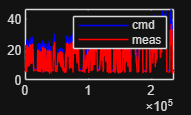

%Motor command compensation
plot(MLt_cmd, 'b');
hold on
plot(FP_tl, 'r');
legend("cmd", "meas")
hold off

% Line of best fit
x = [FP_tl, FP_tr];
y = [MLt_cmd; MRt_cmd]';
m1 = x(:)\y(:)

m1 = 1.2343

Rsq = corrcoef(x, y).^2

Rsq =     1.0000    0.9964
    0.9964    1.0000


percentErrorTorques = mean(abs((y - x)./x)*100)

percentErrorTorques = 19.6645

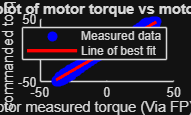

% [coeff, Sc] = polyfit(x,y, 1);
xFit = linspace(min(x), max(x), 1000);
yFit = polyval([m1 0], xFit);


scatter(x, y, 'b','filled')
hold on
plot(xFit, yFit, 'r-', LineWidth=2)
title("Scatter plot of motor torque vs motor command");
ylabel("Motor commanded torque (Nm)");
xlabel("Motor measured torque (Via FP) (Nm)");
legend("Measured data", "Line of best fit")
hold off

% m2 = coeff(1)
% c2 = coeff(2)
% %where line of best fit is y=mx +c
% Sc

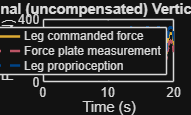

t1 = 90000;
t2 = 110000;
linwidth = 1.5;
t = linspace(0, length(FPz(t1:t2))/1000, length(FPz(t1:t2)));
plot(t, Fz_cmd(t1: t2), LineWidth=linwidth, LineStyle='-', Color='#DDAA33')
hold on
plot(t, FPz(t1:t2), LineWidth=linwidth, LineStyle='--', Color='#BB5566')
plot(t, Fz_read(t1:t2), LineWidth=linwidth, LineStyle='--', Color='#004488' )
legend('Leg commanded force', 'Force plate measurement', 'Leg proprioception');
title('Original (uncompensated) Vertical forces')

xlabel("Time (s)")
ylabel("Force (N)")
hold off